# RefMap tonality/tonal loudness proxy metric development

## Setup

Last modified: 06/11/2025

Comments: Initialised

% choose SHM ECMA-418-2 directory for processing
shmPath = uigetdir("", "Select ECMA-418-2 refmap-psychoacoustics\src\mlab\ root directory");
addpath(genpath(shmPath))

% choose input directory for audio files
inPath = uigetdir("", "Select input directory \02 Delivery\Psychoacoustic metrics\From_Carlos\SynthesisedHovering");
addpath(inPath)

% select article audio files
[inFiles0, inFilepath0] = uigetfile("*.wav", "Select wav files from \02 Delivery\Psychoacoustic metrics\From_Carlos\SynthesisedHovering\Article", inPath, "MultiSelect", "on");
inFilepaths0 = string(fullfile(inFilepath0, inFiles0));

% select added audio files
[inFiles1, inFilepath1] = uigetfile("*.wav", "Select wav files from \02 Delivery\Psychoacoustic metrics\From_Carlos\SynthesisedHovering\Added", inPath, "MultiSelect", "on");
inFilepaths1 = string(fullfile(inFilepath1, inFiles1));

% custom colour palette for line plotting
mycolours = [0, 102, 255;
             0, 204, 153;
             255, 0, 102;
             74, 111, 152;
             231, 144, 29; %251, 164, 49;
             204, 153, 255;
             90, 192, 255;
             90, 255, 243;
             255, 110, 212;
             164, 201, 242;
             255, 254, 139;
             255, 243, 255]./255;

## Process files

% create audio datastore object
ads = audioDatastore(fullfile([inFilepaths0, inFilepaths1]));
filePaths = string(ads.Files);

% % Create transform datastores that calculate metric outputs after reading data
% % from file:
% fdsTECMA = transform(ads, @(signalIn)acousticSHMTonality(signalIn, sampleRate, 1, 'freeFrontal', false, false));
% fdsNQZ4182 = transform(ads, @(signalIn)acousticQuasiLoudZwickerWav(signalIn, sampleRate, 0.1, 1, 'freeFrontal', 'ecma4182'));
% 
% % parallel read all filtered audio using transform datastores
% TonalECMA = readall(fdsTECMA, UseParallel=true);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.


% LoudQZ4182 = readall(fdsNQZ4182, UseParallel=true);

% loop through tonality output and calculate loudness
addAttachedFiles(gcp, filePaths)
parfor ii = 1:length(filePaths)
    [p, sampleRateIn] = audioread(filePaths(ii));
    TonalECMA(ii) = acousticSHMTonality(p, sampleRateIn, 1, 'freeFrontal', false, false);
    LoudQZ4182(ii) = acousticQuasiLoudZwickerWav(p, sampleRateIn, 0.1, 1, 'freeFrontal', 'ecma4182');
    LoudECMA(ii) = acousticSHMLoudnessFromComponent(TonalECMA(ii).specTonalLoudness, TonalECMA(ii).specNoiseLoudness, false, false);
end

for ii = length(ads.Files):-1:1
    [~, filename, ~] = fileparts(ads.Files{ii});
    LoudECMA(ii).File = filename;
    TonalECMA(ii).File = filename;
    LoudQZ4182(ii).File = filename;
end


% calculate total tonal loudness for ECMA-processed files
[loudTDep, loudness] = cellfun(@loudOverall, {TonalECMA.specTonalLoudness}, 'UniformOutput', false);
[TonalECMA.tonalLoudPowAvg] = loudness{:};
[TonalECMA.tonalLoudTDep] = loudTDep{:};

[loudTDep, loudness] = cellfun(@loudOverall, {TonalECMA.specNoiseLoudness}, 'UniformOutput', false);
[TonalECMA.bBandLoudPowAvg] = loudness{:};
[TonalECMA.bBandLoudTDep] = loudTDep{:};


## Compare tonal loudnesses

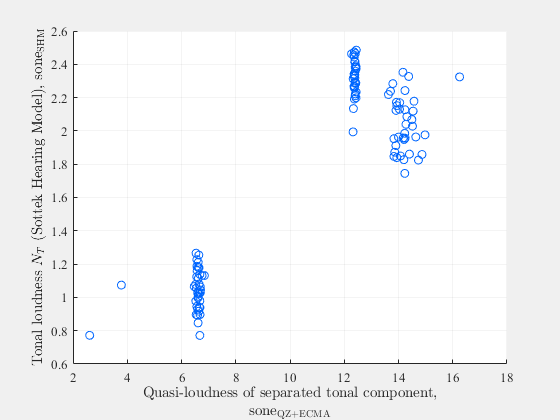

aurMask = contains(ads.Files, ["_Aur", "Total_"]);
tonalMask = contains(ads.Files, "Tonal");
bBandMask = contains(ads.Files, "BroadBand");

TonalECMAAur = TonalECMA(aurMask);
LoudECMATonal = LoudECMA(tonalMask);
LoudQZ4182Tonal = LoudQZ4182(tonalMask);
LoudQZ4182BBand = LoudQZ4182(bBandMask);

labels = ["Yuneec H520", "DJI Mini 3", "DJI Matrice 300", "Xag P40"]

fig = figure;
fig.Visible = 'on';
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "Yn_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "Yn_")).tonalLoudPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.75)
hold on
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "3p_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "3p_")).tonalLoudPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "M3_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "M3_")).tonalLoudPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "X1_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "X1_")).tonalLoudPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.75)
hold off
ylabel("Tonal loudness $N_T$ (Sottek Hearing Model), sone$_\mathrm{SHM}$", 'Interpreter', 'latex')
xlabel(["Quasi-loudness of separated tonal component,"; "sone$_\mathrm{QZ+ECMA}$"], 'Interpreter', 'latex')
legend(labels, 'Location', 'best')
grid('on')
set(gca, 'FontName', 'Times New Roman', 'GridAlpha', 0.05')

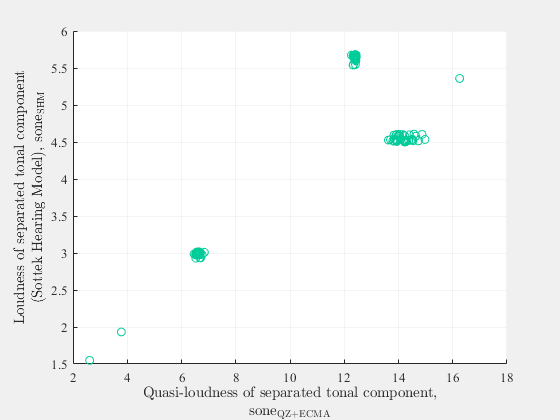


fig = figure;
fig.Visible = 'on';
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "Yn_")).loudPowAvg],...
        [LoudECMATonal(contains({LoudECMATonal.File}, "Yn_")).loudnessPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.75)
hold on
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "3p_")).loudPowAvg],...
        [LoudECMATonal(contains({LoudECMATonal.File}, "3p_")).loudnessPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "M3_")).loudPowAvg],...
        [LoudECMATonal(contains({LoudECMATonal.File}, "M3_")).loudnessPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "X1_")).loudPowAvg],...
        [LoudECMATonal(contains({LoudECMATonal.File}, "X1_")).loudnessPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.75)
hold off
ylabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
xlabel(["Quasi-loudness of separated tonal component,"; "sone$_\mathrm{QZ+ECMA}$"], 'Interpreter', 'latex')
legend(labels, 'Location', 'best')
grid('on')
set(gca, 'FontName', 'Times New Roman', 'GridAlpha', 0.05')

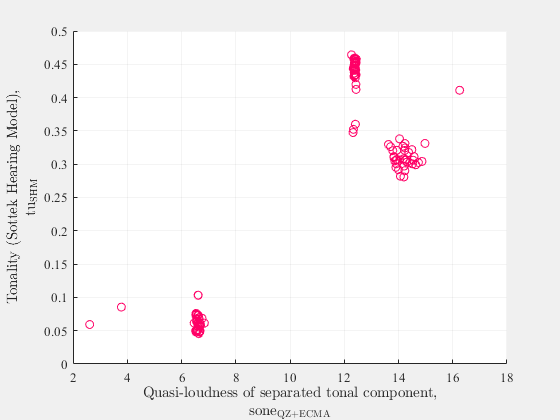


fig = figure;
fig.Visible = 'on';
movegui(fig, 'center')
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "Yn_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "Yn_")).tonalityAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.75)
hold on
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "3p_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "3p_")).tonalityAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "M3_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "M3_")).tonalityAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudQZ4182Tonal(contains({LoudQZ4182Tonal.File}, "X1_")).loudPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "X1_")).tonalityAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.75)
hold off
ylabel(["Tonality (Sottek Hearing Model),"; "tu$_\mathrm{SHM}$"], 'Interpreter', 'latex')
xlabel(["Quasi-loudness of separated tonal component,"; "sone$_\mathrm{QZ+ECMA}$"], 'Interpreter', 'latex')
legend(labels, 'Location', 'best')
grid('on')
set(gca, 'FontName', 'Times New Roman', 'GridAlpha', 0.05')

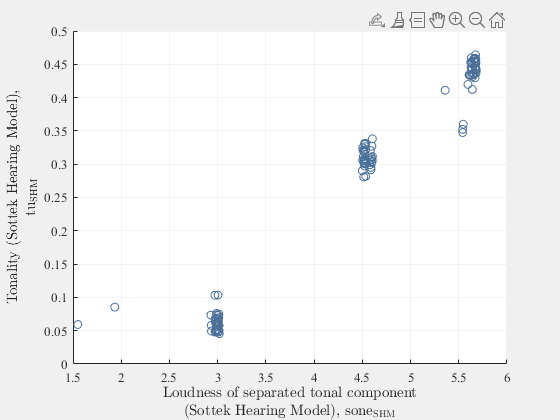


fig = figure;
fig.Visible = 'on';
movegui(fig, 'center')
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "Yn_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "Yn_")).tonalityAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.75)
hold on
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "3p_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "3p_")).tonalityAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "M3_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "M3_")).tonalityAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "X1_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "X1_")).tonalityAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.75)
hold off
ylabel(["Tonality (Sottek Hearing Model),"; "tu$_\mathrm{SHM}$"], 'Interpreter', 'latex')
xlabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
legend(labels, 'Location', 'best')
grid('on')
set(gca, 'FontName', 'Times New Roman', 'GridAlpha', 0.05')


fig = figure;
fig.Visible = 'on';
movegui(fig, 'center')
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "Yn_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "Yn_")).tonalLoudPowAvg], 'h',...
        'MarkerEdgeColor', mycolours(1, :), 'MarkerEdgeAlpha', 0.75)
hold on
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "3p_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "3p_")).tonalLoudPowAvg], '^',...
        'MarkerEdgeColor', mycolours(2, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "M3_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "M3_")).tonalLoudPowAvg], '+',...
        'MarkerEdgeColor', mycolours(3, :), 'MarkerEdgeAlpha', 0.75)
scatter([LoudECMATonal(contains({LoudECMATonal.File}, "X1_")).loudnessPowAvg],...
        [TonalECMAAur(contains({TonalECMAAur.File}, "X1_")).tonalLoudPowAvg], 'x',...
        'MarkerEdgeColor', mycolours(4, :), 'MarkerEdgeAlpha', 0.75)
hold off
ylabel("Tonal loudness $N_T$ (Sottek Hearing Model), sone$_\mathrm{SHM}$", 'Interpreter', 'latex')
xlabel(["Loudness of separated tonal component"; "(Sottek Hearing Model), sone$_\mathrm{SHM}$"], 'Interpreter', 'latex')
legend(labels, 'Location', 'best')
grid('on')
set(gca, 'FontName', 'Times New Roman', 'GridAlpha', 0.05')

## Helper functions

function [loudTDep, loudness] = loudOverall(specLoud)
    loudTDep = sum(specLoud, 2)*0.5;
    loudness = (sum(loudTDep((57 + 1):end, :).^(1/log10(2)), 1)./size(loudTDep((57 + 1):end, :), 1)).^log10(2);
end
